%1
clear
syms z
f=z+2i;
z1=0;
z2=2+2i;
int(f,z,z1,z2)

$$ans = -4+8\,\mathrm{i}$$

%3
clear
syms z
f=2*z-1;
z1=1+1i;
z2=2+3*i;
int(f,z,z1,z2)

$$ans = -6+8\,\mathrm{i}$$

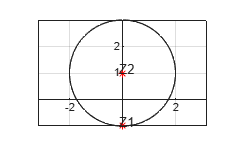

%4
clear
syms z

f=z/(z^2+1);
[sk,var]=numden(f);
[yp_tsk]=solve(var==0,z);

%|z-z0|=r
%|z-1-i|=5/4
%|z-(1+i)|=5/4

z0=1i;
r=2;
C=[real(z0) imag(z0)];

pos=[C-r 2*r 2*r];
x=real(yp_tsk);
y=imag(yp_tsk);

plot(x,y,'r*')
rectangle('Position',pos,'Curvature',[1 1])
axis equal
g=gca;
g.XAxisLocation='origin';
g.YAxisLocation='origin';
grid on

text(real(yp_tsk(1))-0.15,imag(yp_tsk(1))+0.15, 'Z1');
text(real(yp_tsk(2))-0.15,imag(yp_tsk(2))+0.15, 'Z2');


z2=yp_tsk(abs(yp_tsk-z0)<r);
Rez_z2=limit(f*(z-z2),z,z2);

Error using mupadengine/evalin2sym
Limit points must be real, 'infinity', or '-infinity'.

Error in mupadengine/feval2sym_NaNsingularity

Error in sym/limit (line 45)
rSym = feval2sym_NaNsingularity(symengine, 'symobj::map', args{1}.s, 'symobj::limit', args{2}.s, args{3}.s, dir);

Related documentation

integralas=2*pi*1i*Rez_z2

%11
clear
syms z

w=(z^2+4i)/(2*z^2-z);

limit(w,z,inf)

$$ans = \frac{1}{2}$$

%18
clear
syms t
z=1i*t;
dz=diff(z,t);
z1=0;
z2=2*sqrt(2);
int(conj(z)*dz,t,z1,z2)

$$ans = 4$$

%19
clear
syms z

f=(z^2+2)/(z^3*(z-2));

[sk,var]=numden(f);
[yp_tsk]=solve(var==0,z);

z1=yp_tsk(1);
k=3;
isv=diff(f*(z-z1)^k,z,k-1);
Rez_z=limit(isv/factorial(k-1),z,z1)

$$Rez\_z = -\frac{3}{4}$$

%20
clear
syms z
f=z;
z1=0;
z2=1+1i;
int(f,z,z1,z2)

$$ans = \mathrm{i}$$